% load the sound recording of the whiskers on galvo for sup. figures
cd /media/ben/'Extreme SSD'/Thesis/Objects_IC/

[aluminum,sf] = audioread('Aluminumlvo0002178.wav');
attenuated = audioread('Attenuatedlvo0002177.wav');
noObject = audioread("Nonlvo0002176.wav");

galvoT_alum = readtable('Aluminumlvo0002178.txt');
galvoT_att = readtable('Attenuatedlvo0002177.txt');
galvoT_non = readtable('Nonlvo0002176.txt');

alumMouse = audioread('mouse1_aluminum_1.wav');
attMouse = audioread('mouse1_attenuated_1.wav');
noMouse = audioread('mouse1_NoObject_1.wav');

load('whisking_periods_aluminum_1.mat');
load("whisking_periods_attenuated_1.mat");
load("whisking_periods_NoObject_1.mat");

cd /home/ben/Music/Cleaned_audio/
load('volt2pascal.mat')

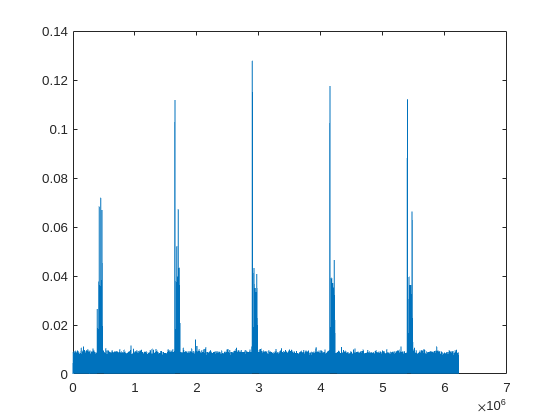

aluminum = aluminum*transferFunction/gainF;
attenuated = attenuated*transferFunction/gainF;
noObject = noObject*transferFunction/gainF;


alumMouse = alumMouse*transferFunction/gainF;
attMouse = attMouse*transferFunction/gainF;

noMouse = noMouse*transferFunction/gainF;


% load an experiment to show compare

timeAlumMouse = round((whisking_periods_aluminum_1(3)*sf) - 0.35*sf);
timeAlumMouse = [timeAlumMouse:timeAlumMouse+1*sf]

timeAlumMouse =     10395266    10395267    10395268    10395269    10395270    10395271    10395272    10395273    10395274    10395275    10395276    10395277    10395278    10395279    10395280    10395281    10395282    10395283    10395284    10395285    10395286    10395287    10395288    10395289    10395290    10395291    10395292    10395293    10395294    10395295    10395296    10395297    10395298    10395299    10395300    10395301    10395302    10395303    10395304    10395305    10395306    10395307    10395308    10395309    10395310    10395311    10395312    10395313    10395314    10395315


timeAlum = round((galvoT_alum.Var1(2)*sf) - sf*1);
timeAlum = [timeAlum:timeAlum+1*sf]

timeAlum =       265645      265646      265647      265648      265649      265650      265651      265652      265653      265654      265655      265656      265657      265658      265659      265660      265661      265662      265663      265664      265665      265666      265667      265668      265669      265670      265671      265672      265673      265674      265675      265676      265677      265678      265679      265680      265681      265682      265683      265684      265685      265686      265687      265688      265689      265690      265691      265692      265693      265694


timeAttMouse = round((whisking_periods_attenuated_1(1)*sf) - 0.38*sf);
timeAttMouse = [timeAttMouse:timeAttMouse+1*sf]

timeAttMouse =     17189216    17189217    17189218    17189219    17189220    17189221    17189222    17189223    17189224    17189225    17189226    17189227    17189228    17189229    17189230    17189231    17189232    17189233    17189234    17189235    17189236    17189237    17189238    17189239    17189240    17189241    17189242    17189243    17189244    17189245    17189246    17189247    17189248    17189249    17189250    17189251    17189252    17189253    17189254    17189255    17189256    17189257    17189258    17189259    17189260    17189261    17189262    17189263    17189264    17189265


timeAtt = round((galvoT_att.Var1(4)*sf) - sf*1);
timeAtt = [timeAtt:timeAtt+1*sf]

timeAtt =      2405443     2405444     2405445     2405446     2405447     2405448     2405449     2405450     2405451     2405452     2405453     2405454     2405455     2405456     2405457     2405458     2405459     2405460     2405461     2405462     2405463     2405464     2405465     2405466     2405467     2405468     2405469     2405470     2405471     2405472     2405473     2405474     2405475     2405476     2405477     2405478     2405479     2405480     2405481     2405482     2405483     2405484     2405485     2405486     2405487     2405488     2405489     2405490     2405491     2405492


timeNoMouse = round((whisking_periods_NoObject_1(5)*sf) - 0.35*sf);
timeNoMouse = [timeNoMouse:timeNoMouse+1*sf]

timeNoMouse =     10030928    10030929    10030930    10030931    10030932    10030933    10030934    10030935    10030936    10030937    10030938    10030939    10030940    10030941    10030942    10030943    10030944    10030945    10030946    10030947    10030948    10030949    10030950    10030951    10030952    10030953    10030954    10030955    10030956    10030957    10030958    10030959    10030960    10030961    10030962    10030963    10030964    10030965    10030966    10030967    10030968    10030969    10030970    10030971    10030972    10030973    10030974    10030975    10030976    10030977


timeNo = round((galvoT_non.Var1(2)*sf) - sf*1);
xTime = round(galvoT_non.Var1(2)*sf-0.5*sf)/250000;
timeNo = [timeNo:timeNo+1*sf]

timeNo =       246460      246461      246462      246463      246464      246465      246466      246467      246468      246469      246470      246471      246472      246473      246474      246475      246476      246477      246478      246479      246480      246481      246482      246483      246484      246485      246486      246487      246488      246489      246490      246491      246492      246493      246494      246495      246496      246497      246498      246499      246500      246501      246502      246503      246504      246505      246506      246507      246508      246509


xTime = timeNo/250000 - xTime

xTime =    -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4999   -0.4998   -0.4998   -0.4998   -0.4998   -0.4998   -0.4998   -0.4998   -0.4998   -0.4998   -0.4998   -0.4998   -0.4998


colorPallete;

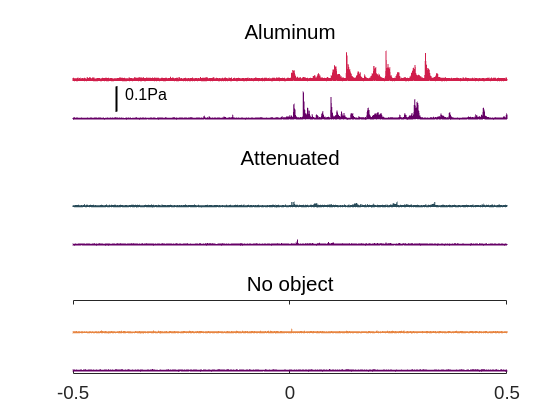

h = figure;
subplot(3,1,1)
plot(xTime,envelope(alumMouse(timeAlumMouse)),"Color",colorBen.purple)  
hold on
plot(xTime,envelope(aluminum(timeAlum))+0.15,"Color",colorBen.aluminum)
title('Aluminum','FontSize',12,'FontWeight','normal')
ylim([-0.01 0.28])
plot([-0.4 -0.4],[0.03 0.13],'k','LineWidth',1.5)
set(gca,'FontSize',14)
set(gca,'FontName','SansSerif')
set(gca, 'xtick', [], 'ytick', []);
set(gca, 'XColor', 'none','YColor','none');
text(-0.38,0.1,"0.1Pa",'FontSize',12,'FontWeight','normal','FontName','SansSerif')

subplot(3,1,2)
plot(xTime,envelope(attMouse(timeAttMouse)),"Color",colorBen.purple)  
hold on
plot(xTime,envelope(attenuated(timeAtt))+0.15,"Color",colorBen.muted)
title('Attenuated','FontSize',12,'FontWeight','normal')
ylim([-0.01 0.28])
set(gca,'FontSize',14)
set(gca,'FontName','SansSerif')
set(gca, 'xtick', [], 'ytick', []);
set(gca, 'XColor', 'none','YColor','none');

subplot(3,1,3)
plot(xTime,envelope(noMouse(timeNoMouse)),"Color",colorBen.purple)  
hold on
plot(xTime,envelope(noObject(timeNo))+0.15,"Color",colorBen.non)
title('No object','FontSize',12,'FontWeight','normal')
ylim([-0.01 0.28])
set(gca,'FontSize',14)
set(gca,'FontName','SansSerif')
set(gca, 'YColor','none');
set(gca,'ytick', []);

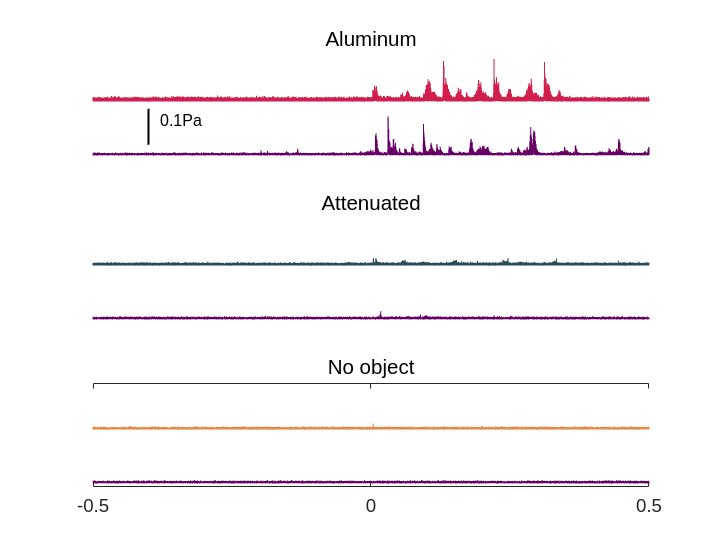

set(gcf,'Position',[2267,71,1058,807]);

cd /media/ben/'Extreme SSD'/Thesis/figures/supplementary
saveas(h,'IC_supp.svg','svg')